HW6 106010006 黃詩瑜

1.

(a)

因為Duality的特性


$$X\left\lbrack n\right\rbrack \Rightarrow^{\textrm{DFT}} \textrm{Nx}\left\lbrack {<-k>}_N \right\rbrack \;$$


將n與k交換


$$\begin{array}{l}
X\left\lbrack k\right\rbrack \Rightarrow^{\textrm{DFT}} \textrm{Nx}\left\lbrack {<-n>}_N \right\rbrack \\
\textrm{DFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace =\textrm{Nx}\left\lbrack {<-n>}_N \right\rbrack \\
\textrm{DFT}\left\lbrace X\left\lbrack {<-k>}_N \right\rbrack \right\rbrace =\textrm{Nx}\left\lbrack n\right\rbrack \\
\frac{1}{N}\textrm{DFT}\left\lbrace X\left\lbrack {<-k>}_N \right\rbrack \right\rbrace =x\left\lbrack n\right\rbrack =\textrm{IDFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace 
\end{array}$$


(b)

先將x[n]轉為$x\left\lbrack {<-n>}_N \right\rbrack$，經過DTF後可得$X\left\lbrack {<-k>}_N \right\rbrack$，再代入function中

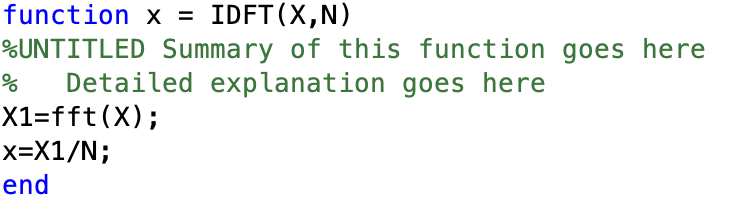

x=[1,8,7,6,5,4,3,2];
X=fft(x);
N=8;
x=IDFT(X,N)

x =      1     2     3     4     5     6     7     8


funtion結果與題目給的x相同，驗證function正確

2.

(a)


$$W_N =e^{-j\frac{2\pi }{N}}$$


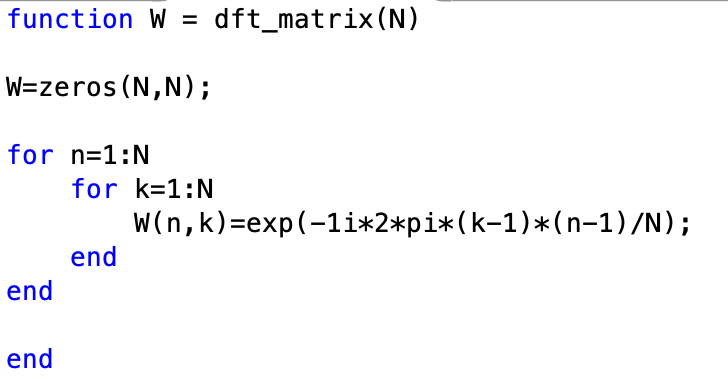

以N=4做測試

N=4;
W=dft_matrix(N)

W =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.0000i   0.0000 - 1.0000i


驗證function正確

(b)

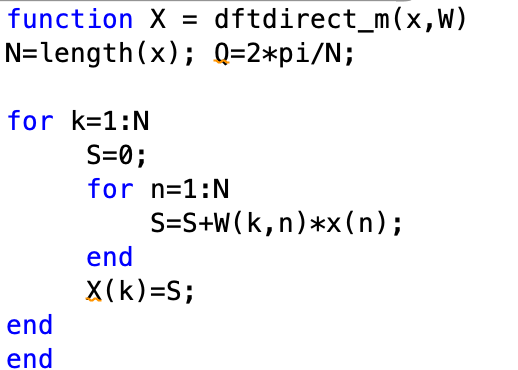

先使用x[n]={0,1,2,3}做測試

x=[0,1,2,3];
N=4;
W=dft_matrix(N);
X1=dftdirect_m(x,W)

X1 =    6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 - 0.0000i  -2.0000 - 2.0000i


X2=fft(x)

X2 =    6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i


經與fft的結果比較後，驗證function正確

N=128;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=dftdirect_m(x,W);
toc

Elapsed time is 0.007017 seconds.


tic
X2=dftdirect(x);
toc

Elapsed time is 0.019129 seconds.


當N=128時，dftdirect花的時間較長，差了1.8倍

N=256;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=dftdirect_m(x,W);
toc

Elapsed time is 0.007552 seconds.


tic
X2=dftdirect(x);
toc

Elapsed time is 0.021793 seconds.


當N=256時，dftdirect花的時間較長，差了2.3倍

N=512;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=dftdirect_m(x,W);
toc

Elapsed time is 0.017304 seconds.


tic
X2=dftdirect(x);
toc

Elapsed time is 0.082305 seconds.


當N=512時，dftdirect花的時間較長，差了3.8倍

N=1024;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=dftdirect_m(x,W);
toc

Elapsed time is 0.081238 seconds.


tic
X2=dftdirect(x);
toc

Elapsed time is 0.654934 seconds.


當N=1024時，dftdirect花的時間較長，差了8倍

(c)

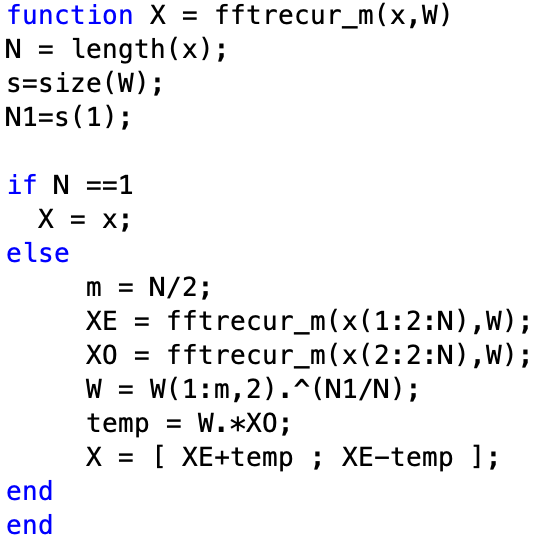

先使用x[n]={0,1,2,3}做測試

x=[0,1,2,3];
N=4;
W=dft_matrix(N);
X1 = fftrecur_m(x,W)

X1 =    6.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 + 0.0000i
  -2.0000 - 2.0000i


X2=fft(x)

X2 =    6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i


經與fft的結果比較後，驗證function正確

N=128;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=fftrecur_m(x,W);
toc

Elapsed time is 0.009165 seconds.


tic
X2=fftrecur(x);
toc

Elapsed time is 0.011520 seconds.


當N=128時，測試了幾次，大部分是fftrecur_m花的時間較長，有時是兩值相近，極少數是fftrecur花的時間較長

N=256;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=fftrecur_m(x,W);
toc

Elapsed time is 0.004454 seconds.


tic
X2=fftrecur(x);
toc

Elapsed time is 0.005043 seconds.


當N=256時，測試了幾次，大部分是fftrecur_m花的時間較長，有時是兩值相近，極少數是fftrecur花的時間較長

N=512;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=fftrecur_m(x,W);
toc

Elapsed time is 0.006312 seconds.


tic
X2=fftrecur(x);
toc

Elapsed time is 0.006064 seconds.


當N=512時，測試了幾次，大部分是fftrecur_m花的時間較長，有時是兩值相近，極少數是fftrecur花的時間較長

N=1024;
W=dft_matrix(N);
x = randn(1,N) + 1j*randn(1,N);

tic
X1=fftrecur_m(x,W);
toc

Elapsed time is 0.011804 seconds.


tic
X2=fftrecur(x);
toc

Elapsed time is 0.009150 seconds.


當N=1024時，測試了幾次，大部分是fftrecur_m花的時間較長

3.

(a)


$$\begin{array}{l}
\textrm{S1}\left\lbrack k\right\rbrack =\textrm{S0}\left\lbrack k\right\rbrack +\textrm{S0}\left\lbrack k+4\right\rbrack W_8^0 \;\;\;\;\textrm{for}\;k=0~3\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{S0}\left\lbrack k-4\right\rbrack -\textrm{S0}\left\lbrack k\right\rbrack W_8^0 \;\;\;\;\textrm{for}\;k=4~7\\
\textrm{S2}\left\lbrack k\right\rbrack =\textrm{S1}\left\lbrack k\right\rbrack +\textrm{S1}\left\lbrack k+2\right\rbrack W_8^0 \;\;\;\;\;\textrm{for}\;k=0~1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{S1}\left\lbrack k+2\right\rbrack +\textrm{S1}\left\lbrack k+4\right\rbrack W_8^2 \;\;\;\;\;\textrm{for}\;k=2~3\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{S1}\left\lbrack k-4\right\rbrack -\textrm{S1}\left\lbrack k-2\right\rbrack W_8^0 \;\;\;\;\;\textrm{for}\;k=4~5\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{S1}\left\lbrack k-2\right\rbrack -\textrm{S1}\left\lbrack k\right\rbrack W_8^2 \;\;\;\;\;\textrm{for}\;k=6~7\\
\textrm{S3}\left\lbrack k\right\rbrack =\textrm{S2}\left\lbrack 2k\right\rbrack +\textrm{S2}\left\lbrack 2k+1\right\rbrack W_8^k \;\;\;\;\textrm{for}\;k=0~3\\
\;\;\;\;\;\;\;\;\;\;\;=\textrm{S2}\left\lbrack 2*\left(k-4\right)\right\rbrack -\textrm{S2}\left\lbrack 2*\left(k-4\right)+1\right\rbrack W_8^{k-4} \;\;\;\textrm{for}\;k=4~7
\end{array}$$


(b)

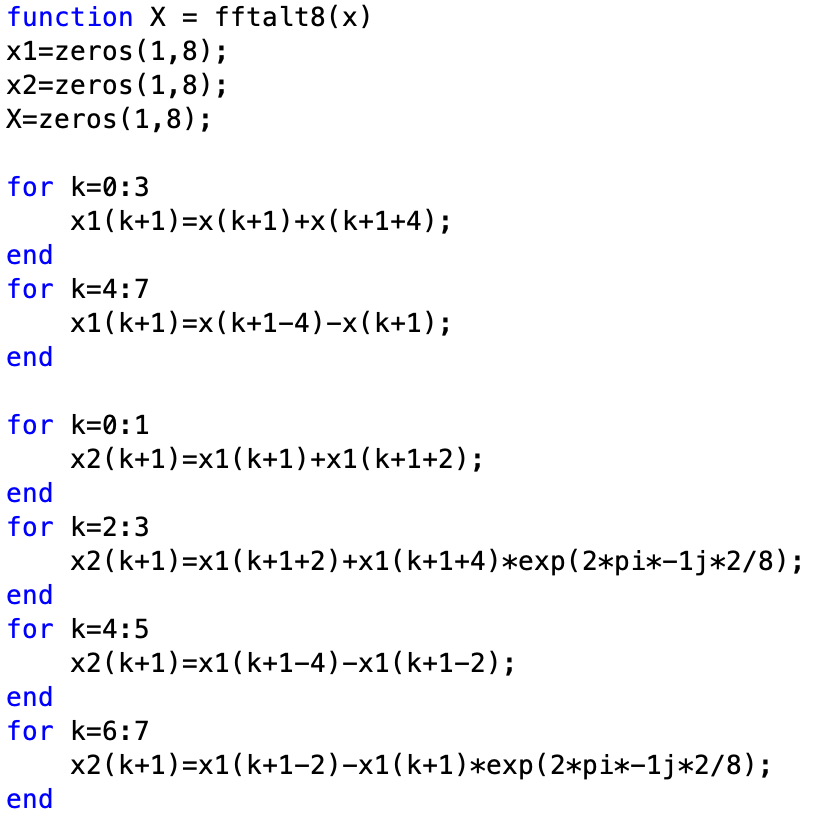

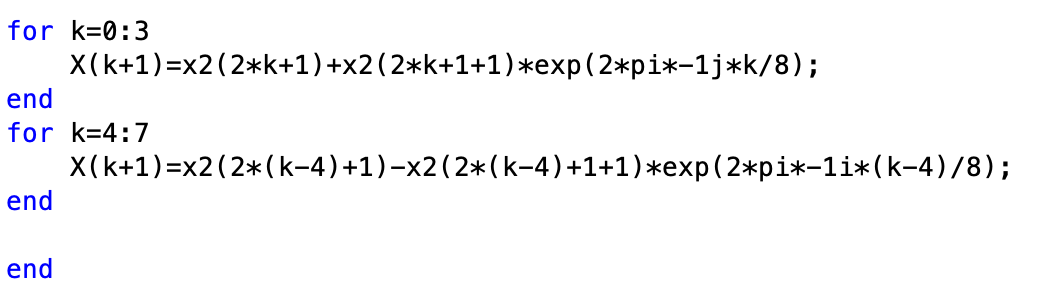

x=[0,1,2,2,3,3,3,4];
X1=fft(x)

X1 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


X2=fftalt8(x)

X2 =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


經過與fft結果比對後，兩者相同，驗證funtion正確

(c)

因為fftditr2使用了bitrevorder funtion，只需要將二進位的值轉換一下，stage的某點所對應到的前一個stage index就能快速的找到，所以能以較簡單的方式計算

而另一個funtion使用natural order，因此較複雜，從Fig 8.10圖中也能看出，規律較少

4.

(a)

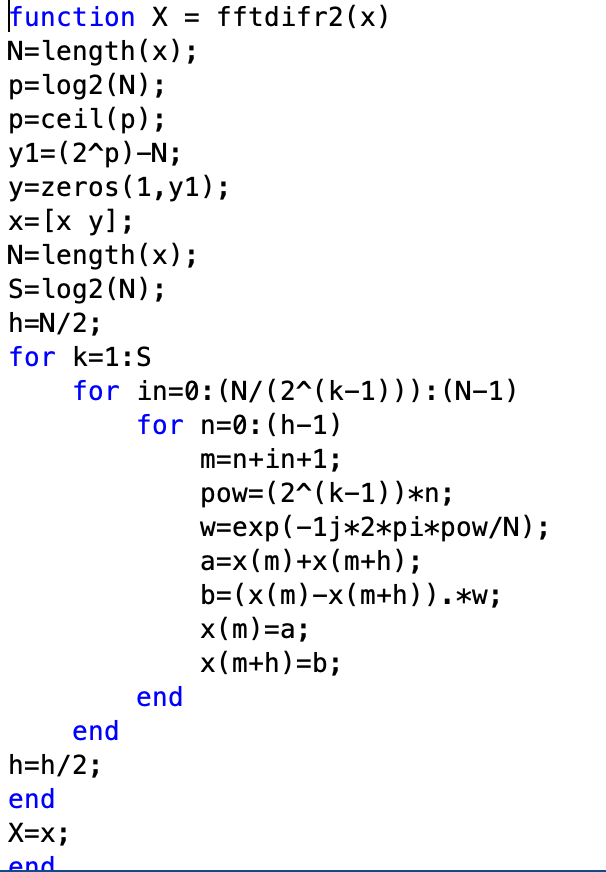

x=[1,2,3,4,5,6,7,8];
X1=fftdifr2(x)

X1 =   36.0000 + 0.0000i  -4.0000 + 0.0000i  -4.0000 + 4.0000i  -4.0000 - 4.0000i  -4.0000 + 9.6569i  -4.0000 - 1.6569i  -4.0000 + 1.6569i  -4.0000 - 9.6569i


X1=bitrevorder(X1)

X1 =   36.0000 + 0.0000i  -4.0000 + 9.6569i  -4.0000 + 4.0000i  -4.0000 + 1.6569i  -4.0000 + 0.0000i  -4.0000 - 1.6569i  -4.0000 - 4.0000i  -4.0000 - 9.6569i


X2=fft(x)

X2 =   36.0000 + 0.0000i  -4.0000 + 9.6569i  -4.0000 + 4.0000i  -4.0000 + 1.6569i  -4.0000 + 0.0000i  -4.0000 - 1.6569i  -4.0000 - 4.0000i  -4.0000 - 9.6569i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

(b)

v=2:

v=2;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =    0.7229 - 0.6519i   1.1090 - 0.8002i   1.2888 + 2.2962i  -1.0473 + 1.9618i


X1=bitrevorder(X1)

X1 =    0.7229 - 0.6519i   1.2888 + 2.2962i   1.1090 - 0.8002i  -1.0473 + 1.9618i


X2=fft(x)

X2 =    0.7229 - 0.6519i   1.2888 + 2.2962i   1.1090 - 0.8002i  -1.0473 + 1.9618i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=3:

v=3;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =   -0.6388 + 1.4476i  -1.4383 + 4.1044i  -0.5768 - 2.3854i   1.9645 - 1.0554i  -0.6774 + 0.2921i   2.1459 + 3.8796i  -6.3883 - 2.8715i  -4.2348 - 7.7138i


X1=bitrevorder(X1)

X1 =   -0.6388 + 1.4476i  -0.6774 + 0.2921i  -0.5768 - 2.3854i  -6.3883 - 2.8715i  -1.4383 + 4.1044i   2.1459 + 3.8796i   1.9645 - 1.0554i  -4.2348 - 7.7138i


X2=fft(x)

X2 =   -0.6388 + 1.4476i  -0.6774 + 0.2921i  -0.5768 - 2.3854i  -6.3883 - 2.8715i  -1.4383 + 4.1044i   2.1459 + 3.8796i   1.9645 - 1.0554i  -4.2348 - 7.7138i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=4:

v=4;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =   -2.8699 + 0.9639i  -0.1359 + 3.2907i   0.1619 - 4.7511i  -1.6948 - 1.6724i  -8.4793 - 2.0574i  -4.0258 - 2.3095i   3.6832 + 0.0987i  -0.5814 - 3.7126i   1.1856 + 1.0836i   0.5572 - 3.6978i  -8.4305 - 2.4848i  -6.2349 - 1.7324i   1.2718 + 5.0888i   0.2368 - 1.6964i  -7.1961 - 0.1224i  -7.8404 - 3.3248i


X1=bitrevorder(X1)

X1 =   -2.8699 + 0.9639i   1.1856 + 1.0836i  -8.4793 - 2.0574i   1.2718 + 5.0888i   0.1619 - 4.7511i  -8.4305 - 2.4848i   3.6832 + 0.0987i  -7.1961 - 0.1224i  -0.1359 + 3.2907i   0.5572 - 3.6978i  -4.0258 - 2.3095i   0.2368 - 1.6964i  -1.6948 - 1.6724i  -6.2349 - 1.7324i  -0.5814 - 3.7126i  -7.8404 - 3.3248i


X2=fft(x)

X2 =   -2.8699 + 0.9639i   1.1856 + 1.0836i  -8.4793 - 2.0574i   1.2718 + 5.0888i   0.1619 - 4.7511i  -8.4305 - 2.4848i   3.6832 + 0.0987i  -7.1961 - 0.1224i  -0.1359 + 3.2907i   0.5572 - 3.6978i  -4.0258 - 2.3095i   0.2368 - 1.6964i  -1.6948 - 1.6724i  -6.2349 - 1.7324i  -0.5814 - 3.7126i  -7.8404 - 3.3248i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=5:

v=5;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =   -6.8237 - 3.9361i  -4.4639 - 5.7693i   1.4753 - 5.1204i  -0.2292 -11.2149i   5.6611 + 4.6929i  -3.9457 + 9.1941i  -7.1423 - 1.5076i  -7.4594 + 6.2693i  -1.3866 - 3.3637i  -0.1367 - 1.3968i   8.4111 - 5.5795i   6.0527 + 2.2503i   4.3666 - 2.5263i  -2.1641 + 4.3190i   0.7829 + 7.6427i   0.3969 - 2.1189i  -0.7731 + 3.6484i   7.9436 + 5.7740i  -1.6684 + 3.6186i   6.5258 + 7.0324i  -9.9273 + 7.6309i  -1.1974 - 7.4356i  10.0318 - 6.7122i  -5.4782 + 7.0991i  -0.1640 + 2.3503i  -7.5027 - 6.3077i  -4.5146 + 5.4790i  -0.4033 - 1.2616i   9.5309 - 4.4049i   0.9726 -10.0878i   3.3647 + 2.7505i  -9.8059 + 2.0657i


X1=bitrevorder(X1)

X1 =   -6.8237 - 3.9361i  -0.7731 + 3.6484i  -1.3866 - 3.3637i  -0.1640 + 2.3503i   5.6611 + 4.6929i  -9.9273 + 7.6309i   4.3666 - 2.5263i   9.5309 - 4.4049i   1.4753 - 5.1204i  -1.6684 + 3.6186i   8.4111 - 5.5795i  -4.5146 + 5.4790i  -7.1423 - 1.5076i  10.0318 - 6.7122i   0.7829 + 7.6427i   3.3647 + 2.7505i  -4.4639 - 5.7693i   7.9436 + 5.7740i  -0.1367 - 1.3968i  -7.5027 - 6.3077i  -3.9457 + 9.1941i  -1.1974 - 7.4356i  -2.1641 + 4.3190i   0.9726 -10.0878i  -0.2292 -11.2149i   6.5258 + 7.0324i   6.0527 + 2.2503i  -0.4033 - 1.2616i  -7.4594 + 6.2693i  -5.4782 + 7.0991i   0.3969 - 2.1189i  -9.8059 + 2.0657i


X2=fft(x)

X2 =   -6.8237 - 3.9361i  -0.7731 + 3.6484i  -1.3866 - 3.3637i  -0.1640 + 2.3503i   5.6611 + 4.6929i  -9.9273 + 7.6309i   4.3666 - 2.5263i   9.5309 - 4.4049i   1.4753 - 5.1204i  -1.6684 + 3.6186i   8.4111 - 5.5795i  -4.5146 + 5.4790i  -7.1423 - 1.5076i  10.0318 - 6.7122i   0.7829 + 7.6427i   3.3647 + 2.7505i  -4.4639 - 5.7693i   7.9436 + 5.7740i  -0.1367 - 1.3968i  -7.5027 - 6.3077i  -3.9457 + 9.1941i  -1.1974 - 7.4356i  -2.1641 + 4.3190i   0.9726 -10.0878i  -0.2292 -11.2149i   6.5258 + 7.0324i   6.0527 + 2.2503i  -0.4033 - 1.2616i  -7.4594 + 6.2693i  -5.4782 + 7.0991i   0.3969 - 2.1189i  -9.8059 + 2.0657i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=6:

v=6;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =    8.4193 + 3.7853i  -8.9154 -17.6951i  -3.1192 - 3.2801i   2.1836 +11.2953i   0.6565 +11.7073i   3.1321 - 2.9089i -11.2084 - 0.5228i  -7.3260 - 8.3428i  -2.9088 - 6.4556i  -0.4029 + 1.2705i  14.2932 + 3.2066i  12.4334 - 2.3941i   4.3994 - 7.9099i   0.2602 + 0.8249i   6.5138 - 3.3329i  -4.7339 - 0.6292i   6.2577 + 2.3820i   8.4940 + 1.4641i  -8.1184 + 4.1415i   1.5475 + 1.8990i  12.0916 +20.4243i   8.3798 +10.8033i -10.7430 - 1.3931i   5.5568 - 6.2089i  -3.5846 - 0.6996i   0.8469 - 2.9660i   1.3636 - 0.1673i  -0.6478 - 5.7092i  13.5808 + 8.3156i  14.9710 -22.3886i   0.3156 - 3.3182i   0.8380 - 0.7071i   1.2007 + 8.2331i   0.0379 - 1.2990i   7.3413 -11.8819i  12.8310 + 3.7149i   3.4815 - 3.1105i -12.5208 +16.0033i  -9.6623 + 3.5464i   8.8753 + 3.8943i -12.1521 +17.8408i   5.7625 - 3.7379i  15.2976 - 1.7816i  -4.3130 - 5.2484i   2.3937 + 3.7526i  17.4491 -10.0283i  -8.2236 - 2.9261i -15.7767 - 2.2706i  -0.9565 - 5.1766i  -0.7633 + 4.3525i


X1=bitrevorder(X1)

X1 =    8.4193 + 3.7853i   1.2007 + 8.2331i   6.2577 + 2.3820i  -0.9565 - 5.1766i  -2.9088 - 6.4556i -12.1521 +17.8408i  -3.5846 - 0.6996i  -3.4578 -11.7529i   0.6565 +11.7073i   3.4815 - 3.1105i  12.0916 +20.4243i  -5.2393 +14.9561i   4.3994 - 7.9099i   2.3937 + 3.7526i  13.5808 + 8.3156i   4.0772 -14.2933i  -3.1192 - 3.2801i   7.3413 -11.8819i  -8.1184 + 4.1415i   3.3259 - 8.9621i  14.2932 + 3.2066i  15.2976 - 1.7816i   1.3636 - 0.1673i   0.6742 + 3.7152i -11.2084 - 0.5228i  -9.6623 + 3.5464i -10.7430 - 1.3931i  -0.5078 - 1.4330i   6.5138 - 3.3329i  -8.2236 - 2.9261i   0.3156 - 3.3182i  12.3460 + 3.2986i  -8.9154 -17.6951i   0.0379 - 1.2990i   8.4940 + 1.4641i  -0.7633 + 4.3525i  -0.4029 + 1.2705i   5.7625 - 3.7379i   0.8469 - 2.9660i  -6.2649 + 2.3292i   3.1321 - 2.9089i -12.5208 +16.0033i   8.3798 +10.8033i   4.4958 + 0.3719i   0.2602 + 0.8249i  17.4491 -10.0283i  14.9710 -22.3886i  -8.8829 + 5.3162i   2.1836 +11.2953i  12.8310 + 3.7149i


X2=fft(x)

X2 =    8.4193 + 3.7853i   1.2007 + 8.2331i   6.2577 + 2.3820i  -0.9565 - 5.1766i  -2.9088 - 6.4556i -12.1521 +17.8408i  -3.5846 - 0.6996i  -3.4578 -11.7529i   0.6565 +11.7073i   3.4815 - 3.1105i  12.0916 +20.4243i  -5.2393 +14.9561i   4.3994 - 7.9099i   2.3937 + 3.7526i  13.5808 + 8.3156i   4.0772 -14.2933i  -3.1192 - 3.2801i   7.3413 -11.8819i  -8.1184 + 4.1415i   3.3259 - 8.9621i  14.2932 + 3.2066i  15.2976 - 1.7816i   1.3636 - 0.1673i   0.6742 + 3.7152i -11.2084 - 0.5228i  -9.6623 + 3.5464i -10.7430 - 1.3931i  -0.5078 - 1.4330i   6.5138 - 3.3329i  -8.2236 - 2.9261i   0.3156 - 3.3182i  12.3460 + 3.2986i  -8.9154 -17.6951i   0.0379 - 1.2990i   8.4940 + 1.4641i  -0.7633 + 4.3525i  -0.4029 + 1.2705i   5.7625 - 3.7379i   0.8469 - 2.9660i  -6.2649 + 2.3292i   3.1321 - 2.9089i -12.5208 +16.0033i   8.3798 +10.8033i   4.4958 + 0.3719i   0.2602 + 0.8249i  17.4491 -10.0283i  14.9710 -22.3886i  -8.8829 + 5.3162i   2.1836 +11.2953i  12.8310 + 3.7149i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=7:

v=7;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =   -8.2014 - 8.0684i   8.6469 - 5.2743i   4.1893 -17.6765i  -5.8488 - 4.0624i  -6.1125 +14.5758i   2.9905 +11.5667i   1.2457 + 4.1967i   0.3025 - 0.2214i   2.2153 + 9.9937i  19.4081 + 8.6482i  14.5871 -18.3099i -20.1292 -10.6074i   8.8967 - 4.9174i   4.5388 - 1.5317i  -7.7535 - 7.2732i -16.3832 - 9.3485i  -2.3735 - 1.9331i   4.1257 - 3.5527i  -0.8152 + 0.1883i   8.8416 + 1.1289i   4.4096 + 2.6043i  11.8503 -15.9983i   7.8675 - 5.1468i  -4.8529 +18.9613i -10.8668 -16.9232i  36.0137 -17.4026i   3.7942 +23.2670i   3.9186 -12.9705i  -9.1447 -19.8175i -10.8173 +16.4302i   6.7243 -17.1983i -22.6591 + 3.2398i -28.2804 - 9.0278i  13.2102 + 1.1316i  13.1802 - 9.8530i   6.5609 + 1.3384i  -2.7732 - 9.0110i  18.6476 +12.6573i -18.9099 +10.3593i -15.7344 +20.4419i -17.0344 - 1.6350i  -4.4887 + 2.0859i  -3.2436 - 6.2563i  -0.0347 - 1.4777i  10.7952 +10.8556i   5.4700 -11.1061i  -9.0535 + 1.5303i  -0.3653 +12.1175i  21.5213 - 7.5567i  -2.1940 + 4.6690i


X1=bitrevorder(X1)

X1 =   -8.2014 - 8.0684i  -0.6122 + 2.5266i -28.2804 - 9.0278i  11.8084 + 6.1246i  -2.3735 - 1.9331i  12.6877 -21.5308i  21.5213 - 7.5567i -14.0198 -13.7147i   2.2153 + 9.9937i  -9.4911 - 2.9959i -17.0344 - 1.6350i  -5.2571 + 1.1647i -10.8668 -16.9232i -33.4793 -24.9874i  -6.6928 -21.1947i   7.4131 + 5.5384i  -6.1125 +14.5758i   3.2867 + 1.0285i  -2.7732 - 9.0110i  -1.4341 + 3.6182i   4.4096 + 2.6043i  16.5754 + 0.1240i -17.6021 + 1.2232i   5.6908 - 3.8077i   8.8967 - 4.9174i -10.1034 + 3.3580i  10.7952 +10.8556i   6.5715 - 2.3846i  -9.1447 -19.8175i  -7.6770 - 3.0486i -24.6980 -19.0483i -11.3014 -13.0960i   4.1893 -17.6765i  -9.7322 - 1.3881i  13.1802 - 9.8530i  10.5859 - 7.5253i  -0.8152 + 0.1883i   3.8191 +16.5627i  18.4902 -15.3988i   7.9051 -15.6571i  14.5871 -18.3099i   2.3290 - 8.6706i  -3.2436 - 6.2563i -19.7302 + 0.7068i   3.7942 +23.2670i  -1.4470 - 0.7782i  -1.7089 - 1.5889i   7.1999 +25.1596i   1.2457 + 4.1967i  -1.9669 - 5.5337i


X2=fft(x)

X2 =   -8.2014 - 8.0684i  -0.6122 + 2.5266i -28.2804 - 9.0278i  11.8084 + 6.1246i  -2.3735 - 1.9331i  12.6877 -21.5308i  21.5213 - 7.5567i -14.0198 -13.7147i   2.2153 + 9.9937i  -9.4911 - 2.9959i -17.0344 - 1.6350i  -5.2571 + 1.1647i -10.8668 -16.9232i -33.4793 -24.9874i  -6.6928 -21.1947i   7.4131 + 5.5384i  -6.1125 +14.5758i   3.2867 + 1.0285i  -2.7732 - 9.0110i  -1.4341 + 3.6182i   4.4096 + 2.6043i  16.5754 + 0.1240i -17.6021 + 1.2232i   5.6908 - 3.8077i   8.8967 - 4.9174i -10.1034 + 3.3580i  10.7952 +10.8556i   6.5715 - 2.3846i  -9.1447 -19.8175i  -7.6770 - 3.0486i -24.6980 -19.0483i -11.3014 -13.0960i   4.1893 -17.6765i  -9.7322 - 1.3881i  13.1802 - 9.8530i  10.5859 - 7.5253i  -0.8152 + 0.1883i   3.8191 +16.5627i  18.4902 -15.3988i   7.9051 -15.6571i  14.5871 -18.3099i   2.3290 - 8.6706i  -3.2436 - 6.2563i -19.7302 + 0.7068i   3.7942 +23.2670i  -1.4470 - 0.7782i  -1.7089 - 1.5889i   7.1999 +25.1596i   1.2457 + 4.1967i  -1.9669 - 5.5337i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=8:

v=8;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =  -21.3933 -25.0174i -19.3975 + 2.9685i   8.6069 + 8.3580i   0.8042 - 2.4033i -12.2043 -34.1398i -13.8220 -24.2558i  -9.8977 -14.5485i   9.5760 -32.7288i   4.6448 - 7.1133i -14.4220 -19.8486i  22.5799 -33.3235i -23.3824 + 0.2052i  34.5709 - 6.0324i -28.3301 -16.2937i  40.5374 - 1.5970i  19.7126 +21.5636i -21.3006 -18.6108i  22.6363 -38.0082i  11.5458 - 2.6519i  27.2771 - 2.9483i  -7.9025 +15.9699i  -9.1755 -16.8086i  -0.5506 +18.7312i   4.1572 -30.3838i   8.4665 +17.8278i  19.1322 + 1.4413i  18.9466 - 7.7018i  25.7991 + 5.6033i  -1.1254 -15.3665i -25.3532 + 4.0174i -24.2593 -22.6626i  13.6118 +19.6594i   4.0764 + 5.3076i  15.8153 + 7.0065i  21.2554 - 1.0576i  29.5400 - 1.5728i -19.3487 + 0.8792i -10.9529 +13.2844i  -3.1464 + 6.1328i  -0.4820 +20.8320i -18.8070 +13.6977i -24.1851 +14.5813i  -2.1182 - 2.6880i  -0.9253 - 5.3307i  -4.0943 - 9.5051i  -4.8705 - 5.6358i -11.2778 - 1.7746i  -1.4563 + 1.0015i  26.7094 + 6.8833i  15.1451 -22.8288i


X1=bitrevorder(X1)

X1 =  -21.3933 -25.0174i -10.1746 +18.1729i  -7.8854 -12.4340i  -8.2055 +37.9570i   4.0764 + 5.3076i -17.4536 +18.3762i -15.7539 - 7.6762i  18.0979 -16.1037i -21.3006 -18.6108i -10.5201 + 8.1835i  -4.3617 + 0.5511i  -6.3836 -22.8514i  26.7094 + 6.8833i  12.9211 +10.3357i   1.8605 + 9.1057i -14.2595 + 3.6603i   4.6448 - 7.1133i  15.3207 +15.4206i   8.7702 + 9.6733i   3.3717 -14.5293i -18.8070 +13.6977i  -5.0494 - 4.1448i -14.1470 +10.3226i -11.6903 -22.3061i   8.4665 +17.8278i  -4.3035 + 9.2928i -35.7794 +32.2039i   9.5489 -19.4585i  -5.2010 -10.7387i  -7.8066 -15.3155i   7.6117 +11.5199i   4.7271 -12.4785i -12.2043 -34.1398i  -3.1366 - 8.0394i  14.3597 +26.9357i -11.5777 -10.8997i -19.3487 + 0.8792i -18.4243 - 2.9685i   5.6560 - 1.3870i   0.8485 +30.6487i  -7.9025 +15.9699i  -7.9041 - 1.2603i  11.7880 +11.8250i   3.5990 -33.9869i  15.0284 -18.9572i  -5.8359 +10.6079i  31.3915 + 9.3163i  -3.6141 + 3.7086i  34.5709 - 6.0324i  -0.0476 - 0.1533i


X2=fft(x)

X2 =  -21.3933 -25.0174i -10.1746 +18.1729i  -7.8854 -12.4340i  -8.2055 +37.9570i   4.0764 + 5.3076i -17.4536 +18.3762i -15.7539 - 7.6762i  18.0979 -16.1037i -21.3006 -18.6108i -10.5201 + 8.1835i  -4.3617 + 0.5511i  -6.3836 -22.8514i  26.7094 + 6.8833i  12.9211 +10.3357i   1.8605 + 9.1057i -14.2595 + 3.6603i   4.6448 - 7.1133i  15.3207 +15.4206i   8.7702 + 9.6733i   3.3717 -14.5293i -18.8070 +13.6977i  -5.0494 - 4.1448i -14.1470 +10.3226i -11.6903 -22.3061i   8.4665 +17.8278i  -4.3035 + 9.2928i -35.7794 +32.2039i   9.5489 -19.4585i  -5.2010 -10.7387i  -7.8066 -15.3155i   7.6117 +11.5199i   4.7271 -12.4785i -12.2043 -34.1398i  -3.1366 - 8.0394i  14.3597 +26.9357i -11.5777 -10.8997i -19.3487 + 0.8792i -18.4243 - 2.9685i   5.6560 - 1.3870i   0.8485 +30.6487i  -7.9025 +15.9699i  -7.9041 - 1.2603i  11.7880 +11.8250i   3.5990 -33.9869i  15.0284 -18.9572i  -5.8359 +10.6079i  31.3915 + 9.3163i  -3.6141 + 3.7086i  34.5709 - 6.0324i  -0.0476 - 0.1533i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

v=9:

v=9;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 =   11.7374 +19.2580i  -1.5494 - 3.5599i  32.4100 -10.3755i -41.7286 -15.6503i -32.2043 -14.9058i  -9.6688 +21.2460i   8.4395 -13.3335i  34.0397 -34.1783i -11.4790 +17.4430i   7.3907 +24.5862i -33.1452 - 6.5323i   4.0608 +11.3884i -24.2747 -24.8983i  -3.9056 +18.3281i  -8.0454 + 3.6505i -29.3220 + 4.1903i  34.6911 +13.2993i  14.1857 +34.1742i -20.2069 + 3.7114i  -4.9602 - 0.0870i  -9.2041 + 4.0090i  28.4111 + 4.0879i  -2.6820 -24.9277i   3.0854 +21.3690i  -7.4917 - 8.7388i -10.5316 - 9.7201i  20.3125 -20.9472i -22.0475 - 2.5358i  -6.6722 +10.3196i  15.6930 +15.1885i  15.7142 +15.3864i   6.7421 -18.8201i -12.3603 + 5.2998i -42.5940 - 6.5972i -32.8944 -13.3179i  26.0673 +25.6876i -11.1262 -16.9503i  -7.2848 +18.1550i -11.2737 - 4.1074i  16.4468 +40.0031i  18.9800 +18.4222i -12.5150 +23.8544i  17.9913 - 0.6784i -20.0987 +28.7363i   6.3595 + 6.6989i   8.2980 + 1.4829i  22.1159 +21.7299i  -0.9030 -15.5785i -20.0802 -34.6356i -15.9099 + 3.6698i


X1=bitrevorder(X1)

X1 =   11.7374 +19.2580i  14.1321 -13.5540i   6.5551 +36.2684i   7.7291 - 1.8899i  -5.9365 -31.9807i   3.0188 +16.2815i  10.7699 +75.1079i -25.2365 -60.7864i -12.3603 + 5.2998i  22.2993 -11.8776i -21.4685 - 4.5595i   4.5532 + 7.3988i  -6.1314 -18.9563i   0.5960 -15.0736i -23.3952 + 0.6956i   9.3958 -33.1064i  34.6911 +13.2993i -34.5860 - 7.5669i  11.7634 -29.1856i -23.3138 +15.5234i   3.1379 -15.5559i -33.2967 -25.7505i  27.6569 - 1.1259i   3.9609 +30.6448i -20.0802 -34.6356i  49.9179 +25.0929i  15.4230 +30.6751i  -5.1596 -14.9448i -20.8116 +44.2114i   2.0931 +14.5329i   3.7968 -43.7721i  34.2404 +29.5552i -11.4790 +17.4430i  24.2472 +40.2915i  33.8887 - 2.3355i   8.6277 - 4.5041i  -7.4823 +22.4954i  12.1615 - 0.4172i  26.9107 + 2.2525i -32.7128 -31.5704i  18.9800 +18.4222i  -0.7184 - 2.1099i  17.1986 - 6.1446i  14.8019 +47.1602i  10.8114 +35.3234i  39.6372 + 1.9709i  18.1904 +40.8647i  27.3591 +17.1483i  -7.4917 - 8.7388i  14.8158 +20.6185i


X2=fft(x)

X2 =   11.7374 +19.2580i  14.1321 -13.5540i   6.5551 +36.2684i   7.7291 - 1.8899i  -5.9365 -31.9807i   3.0188 +16.2815i  10.7699 +75.1079i -25.2365 -60.7864i -12.3603 + 5.2998i  22.2993 -11.8776i -21.4685 - 4.5595i   4.5532 + 7.3988i  -6.1314 -18.9563i   0.5960 -15.0736i -23.3952 + 0.6956i   9.3958 -33.1064i  34.6911 +13.2993i -34.5860 - 7.5669i  11.7634 -29.1856i -23.3138 +15.5234i   3.1379 -15.5559i -33.2967 -25.7505i  27.6569 - 1.1259i   3.9609 +30.6448i -20.0802 -34.6356i  49.9179 +25.0929i  15.4230 +30.6751i  -5.1596 -14.9448i -20.8116 +44.2114i   2.0931 +14.5329i   3.7968 -43.7721i  34.2404 +29.5552i -11.4790 +17.4430i  24.2472 +40.2915i  33.8887 - 2.3355i   8.6277 - 4.5041i  -7.4823 +22.4954i  12.1615 - 0.4172i  26.9107 + 2.2525i -32.7128 -31.5704i  18.9800 +18.4222i  -0.7184 - 2.1099i  17.1986 - 6.1446i  14.8019 +47.1602i  10.8114 +35.3234i  39.6372 + 1.9709i  18.1904 +40.8647i  27.3591 +17.1483i  -7.4917 - 8.7388i  14.8158 +20.6185i


v=10:

v=10;
N=2^v;
x = randn(1,N) + 1j*randn(1,N);
X1=fftdifr2(x)

X1 = 	1.0e+02 *

   0.2291 - 0.4560i   0.1195 - 0.0094i  -0.1656 - 0.1888i   0.5078 - 0.0604i  -0.4553 + 0.5151i  -0.2263 - 0.2815i   0.1638 + 0.8951i  -0.1407 + 0.3673i  -0.1119 + 0.2744i  -0.0318 + 0.2329i   0.6611 + 0.4303i   0.7013 + 0.6769i  -0.1492 - 0.1785i  -0.2001 - 0.0353i  -0.1610 + 0.2774i  -0.1426 - 0.4466i   0.0825 - 0.0054i   0.0937 - 0.4329i  -0.3778 - 0.5735i   0.3858 + 0.1849i  -0.1460 + 0.1233i  -0.2498 + 0.3040i  -0.3521 + 0.2604i  -0.1165 - 0.4233i   0.2359 - 0.1150i  -0.0790 - 0.0663i  -0.6497 - 0.0938i   0.2146 + 0.0410i   0.3764 + 0.2022i  -0.2577 + 0.2954i   0.0381 - 0.2347i   0.1686 + 0.0695i   0.0296 + 0.2317i   0.0542 - 0.0747i  -0.1040 + 0.6635i  -0.3929 + 0.1296i  -0.1850 + 0.2819i   0.1841 - 0.2823i   0.3388 + 0.2996i  -0.1002 + 0.4761i  -0.0865 - 0.2020i   0.0212 + 0.0309i  -0.5126 - 0.0890i  -0.1370 - 0.1290i  -0.3371 + 0.1645i   0.0374 + 0.1857i  -0.2909 + 0.2648i  -0.0794 - 0.4828i  -0.0134 - 0.1844i  -0.2168 - 0.2664i


X1=bitrevorder(X1)

X1 = 	1.0e+02 *

   0.2291 - 0.4560i   0.0540 - 0.0919i  -0.1695 - 0.2888i  -0.2992 - 0.1905i   0.0899 + 0.0693i   0.2113 + 0.1071i  -0.2278 + 0.2324i   0.3475 + 0.3057i  -0.0956 - 0.0468i   0.2148 - 0.0973i  -0.8891 - 0.2627i   0.4512 + 0.1965i   0.1221 + 0.7020i  -0.3202 - 0.1417i   0.1414 + 0.0927i   0.6490 + 0.1329i   0.0296 + 0.2317i  -0.2229 + 0.0235i   0.0069 - 0.6728i  -0.5010 + 0.0940i   0.0953 + 0.0569i  -0.1545 + 0.0963i   0.2559 + 0.1215i   0.0712 - 0.3873i  -0.0079 - 0.1169i   0.0364 - 0.3020i  -0.7683 - 0.3013i  -0.1718 - 0.3518i  -0.4225 + 0.5301i  -0.5112 + 0.1746i  -0.1699 + 0.0344i  -0.2514 + 0.0396i   0.0825 - 0.0054i  -0.3371 + 0.0656i   0.2687 + 0.0399i   0.0635 - 0.2271i  -0.1550 - 0.0719i  -0.0692 - 0.0571i  -0.1698 - 0.0292i  -0.3908 + 0.1962i  -0.0941 + 0.1569i  -0.1526 + 0.5035i  -0.1734 + 0.3671i  -0.2471 + 0.3996i   0.4225 - 0.4357i  -0.4659 - 0.0203i  -0.7440 + 0.3946i  -0.4442 - 0.7051i  -0.0134 - 0.1844i   0.1800 + 0.2977i


X2=fft(x)

X2 = 	1.0e+02 *

   0.2291 - 0.4560i   0.0540 - 0.0919i  -0.1695 - 0.2888i  -0.2992 - 0.1905i   0.0899 + 0.0693i   0.2113 + 0.1071i  -0.2278 + 0.2324i   0.3475 + 0.3057i  -0.0956 - 0.0468i   0.2148 - 0.0973i  -0.8891 - 0.2627i   0.4512 + 0.1965i   0.1221 + 0.7020i  -0.3202 - 0.1417i   0.1414 + 0.0927i   0.6490 + 0.1329i   0.0296 + 0.2317i  -0.2229 + 0.0235i   0.0069 - 0.6728i  -0.5010 + 0.0940i   0.0953 + 0.0569i  -0.1545 + 0.0963i   0.2559 + 0.1215i   0.0712 - 0.3873i  -0.0079 - 0.1169i   0.0364 - 0.3020i  -0.7683 - 0.3013i  -0.1718 - 0.3518i  -0.4225 + 0.5301i  -0.5112 + 0.1746i  -0.1699 + 0.0344i  -0.2514 + 0.0396i   0.0825 - 0.0054i  -0.3371 + 0.0656i   0.2687 + 0.0399i   0.0635 - 0.2271i  -0.1550 - 0.0719i  -0.0692 - 0.0571i  -0.1698 - 0.0292i  -0.3908 + 0.1962i  -0.0941 + 0.1569i  -0.1526 + 0.5035i  -0.1734 + 0.3671i  -0.2471 + 0.3996i   0.4225 - 0.4357i  -0.4659 - 0.0203i  -0.7440 + 0.3946i  -0.4442 - 0.7051i  -0.0134 - 0.1844i   0.1800 + 0.2977i


將function的output經過bit reversal轉換後，fft結果比對，驗證funtion正確

5.

(a)

先判斷Type再按照公式建funtion


$$\begin{array}{l}
\textrm{for}\;\textrm{type}\;1\\
y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M}{2}-1} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack +x\left\lbrack n-M+k\right\rbrack \right)+h\left\lbrack \frac{M}{2}\right\rbrack x\left\lbrack n-\frac{M}{2}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
\textrm{for}\;\textrm{type}\;2\\
y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M-1}{2}} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack +x\left\lbrack n-M+k\right\rbrack \right)
\end{array}$$



$$\begin{array}{l}
\textrm{for}\;\textrm{type}\;3\\
y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M}{2}-1} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack -x\left\lbrack n-M+k\right\rbrack \right)
\end{array}$$



$$\begin{array}{l}
\textrm{for}\;\textrm{type}\;4\\
y\left\lbrack n\right\rbrack =\sum_{k=0}^{\frac{M-1}{2}} h\left\lbrack k\right\rbrack \left(x\left\lbrack n-k\right\rbrack -x\left\lbrack n-M+k\right\rbrack \right)
\end{array}$$


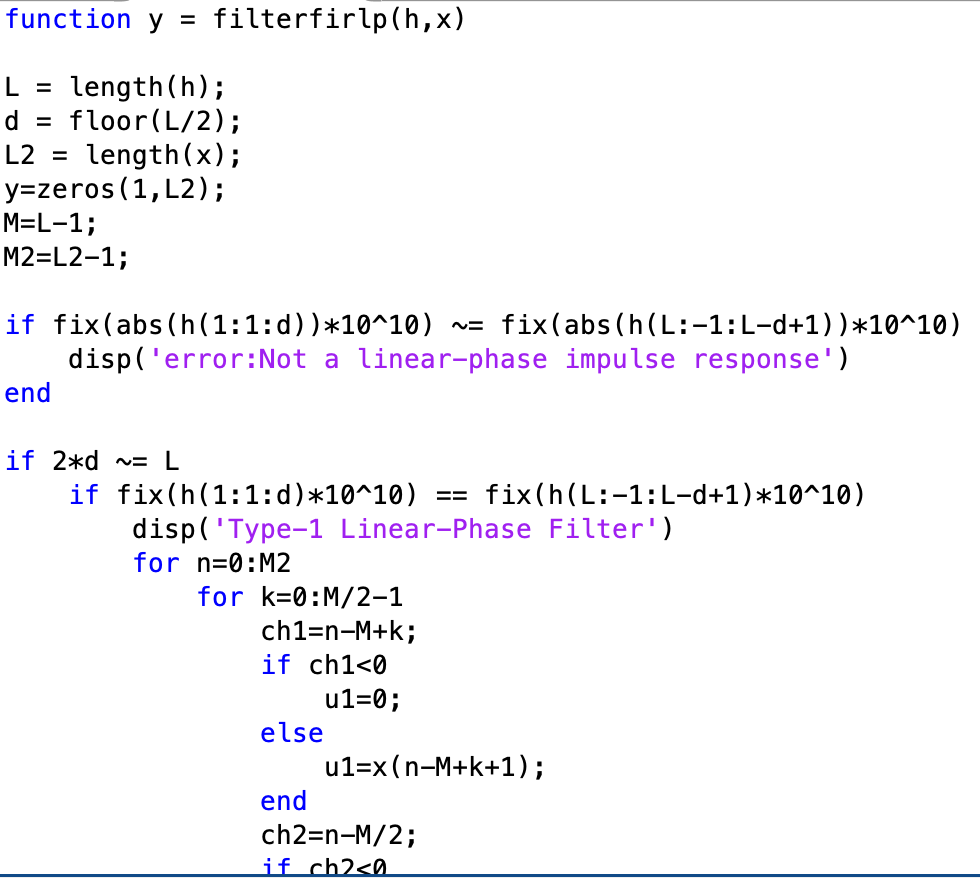

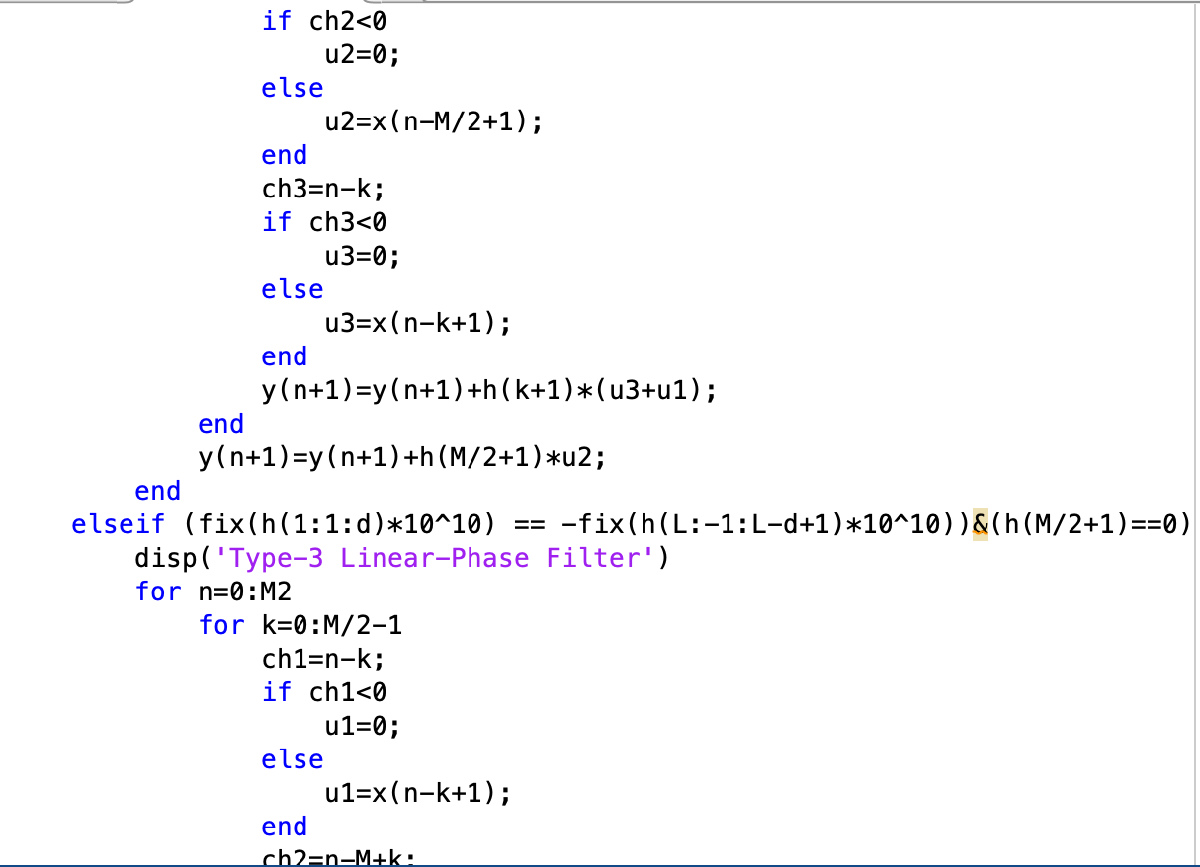

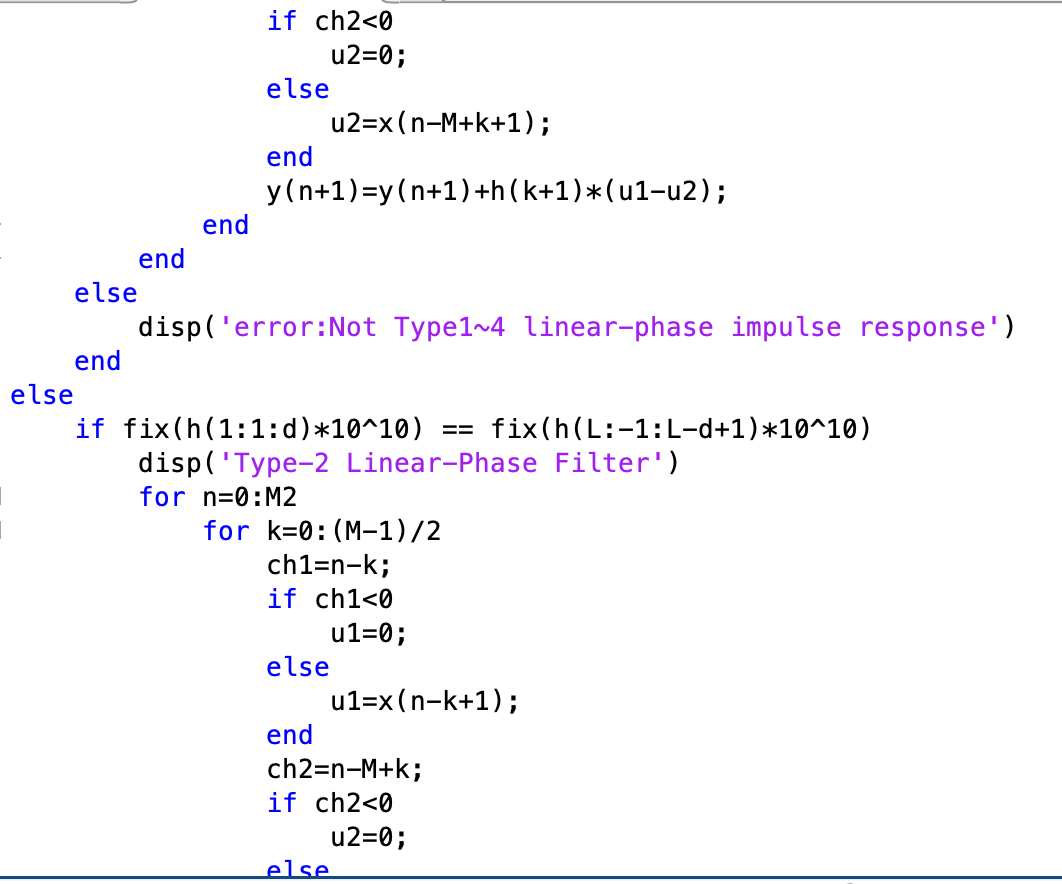

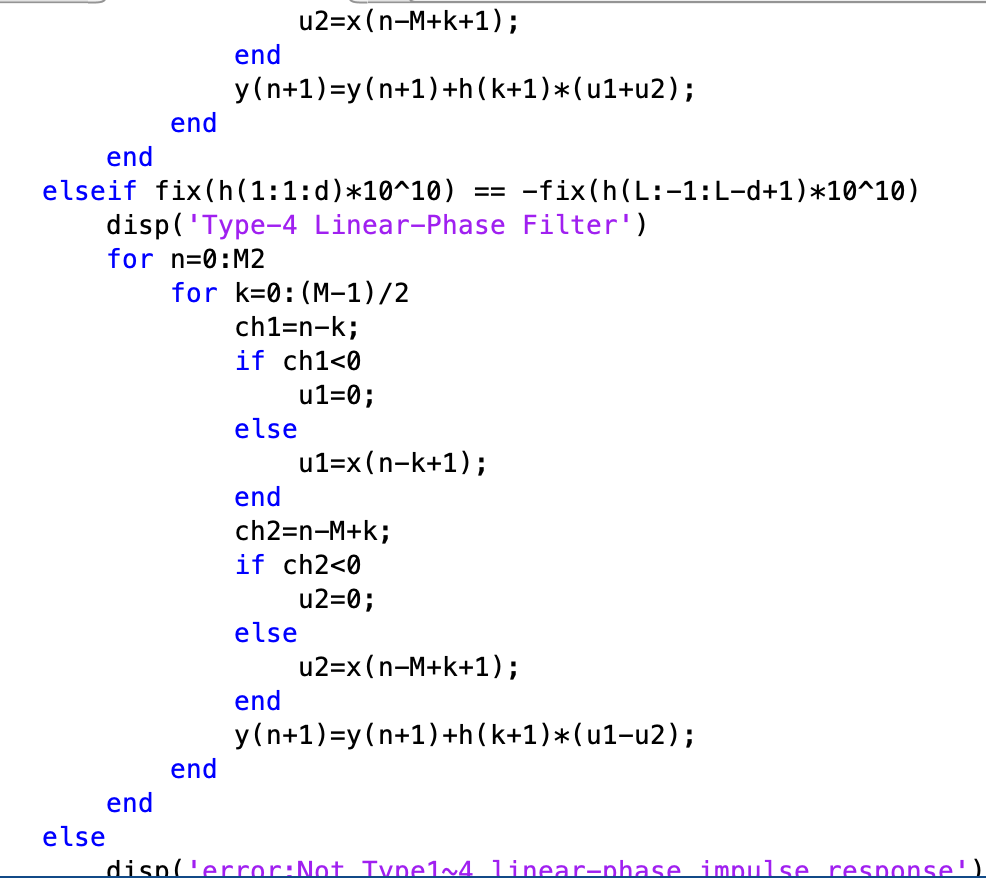

(b)

step response is the response to the unit step function

x=ones(1,10);
h1=[1,2,3,2,1];
y1=filterfirlp(h1,x)

Type-1 Linear-Phase Filter


y1 =      1     3     6     8     9     9     9     9     9     9


y2=filter(h1,1,x)

y2 =      1     3     6     8     9     9     9     9     9     9


h2=[1,-2,3,3,-2,1];
y1=filterfirlp(h2,x)

Type-2 Linear-Phase Filter


y1 =      1    -1     2     5     3     4     4     4     4     4


y2=filter(h2,1,x)

y2 =      1    -1     2     5     3     4     4     4     4     4


h3=[1,-5,0,5,-1];
y1=filterfirlp(h3,x)

Type-3 Linear-Phase Filter


y1 =      1    -4    -4     1     0     0     0     0     0     0


y2=filter(h3,1,x)

y2 =      1    -4    -4     1     0     0     0     0     0     0


h4=[1,-3,-4,4,3,-1];
y1=filterfirlp(h4,x)

Type-4 Linear-Phase Filter


y1 =      1    -2    -6    -2     1     0     0     0     0     0


y2=filter(h4,1,x)

y2 =      1    -2    -6    -2     1     0     0     0     0     0


h5=[3,2,3,-2,-3];
y1=filterfirlp(h5,x)

error:Not Type1~4 linear-phase impulse response


y1 =      0     0     0     0     0     0     0     0     0     0


y2=filter(h5,1,x)

y2 =      3     5     8     6     3     3     3     3     3     3


將filterfirlp的結果與filter比對可看出h1~h4都相同，而h5因為不符合type1~4，因此顯示error

驗證filterfirlp正確

6.

(a)

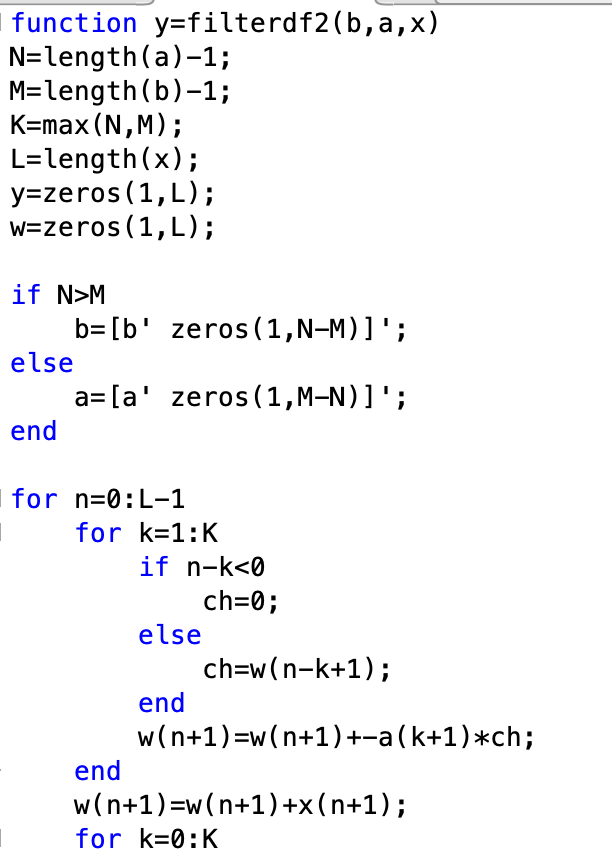

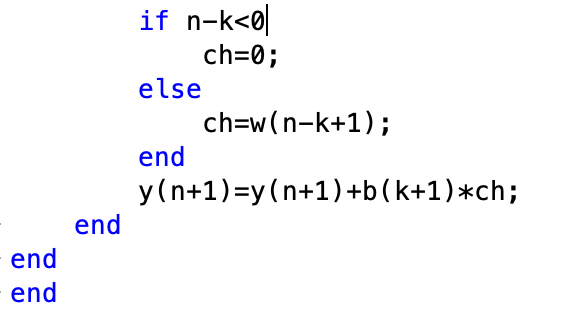

(b)

n=0:1:500;
x = (1/4).^n;
a=[1,-3/2,1/2];
b=1;
y1=filterdf1(b,a,x)

y1 =     1.0000    1.7500    2.1875    2.4219    2.5430    2.6045    2.6355    2.6511    2.6589    2.6628    2.6647    2.6657    2.6662    2.6664    2.6665    2.6666    2.6666    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667


y2=filterdf2(b,a,x)

y2 =     1.0000    1.7500    2.1875    2.4219    2.5430    2.6045    2.6355    2.6511    2.6589    2.6628    2.6647    2.6657    2.6662    2.6664    2.6665    2.6666    2.6666    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667    2.6667


y1==y2

ans = 1×501 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


將filterdf1和filterdf2的結果做比較，兩者完全相同

驗證function正確

7.

b=[1,-2.61,2.75,-1.36,0.27];
a=[1,-1.05,0.91,-0.8,0.38];
[sos,G]=tf2sos(b,a)

sos =     1.0000   -1.4066    0.6260    1.0000   -1.3076    0.5305
    1.0000   -1.2034    0.4313    1.0000    0.2576    0.7163


G = 1

經過tf2sos function後，可將H(z)化簡為$1\times \frac{1-1\ldotp 4066Z^{-1} +0\ldotp 626Z^{-2} }{1-1\ldotp 3076Z^{-1} +0\ldotp 5305Z^{-2} }+$$\frac{1-1\ldotp 2034Z^{-1} +0\ldotp 4313Z^{-2} }{1+0\ldotp 2576Z^{-1} +0\ldotp 7163Z^{-2} }$

(a)

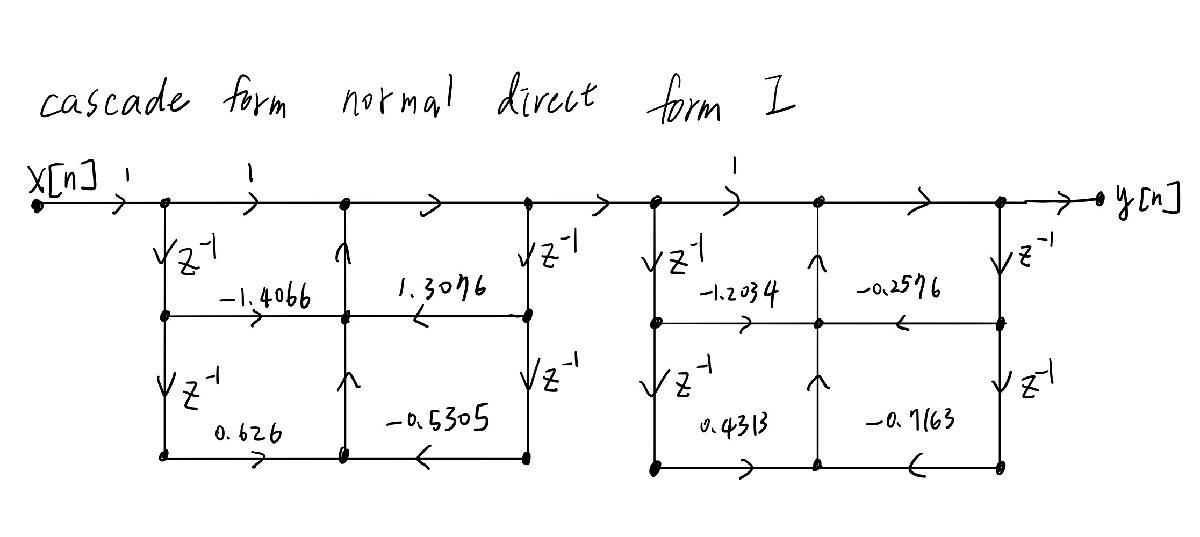

(b)

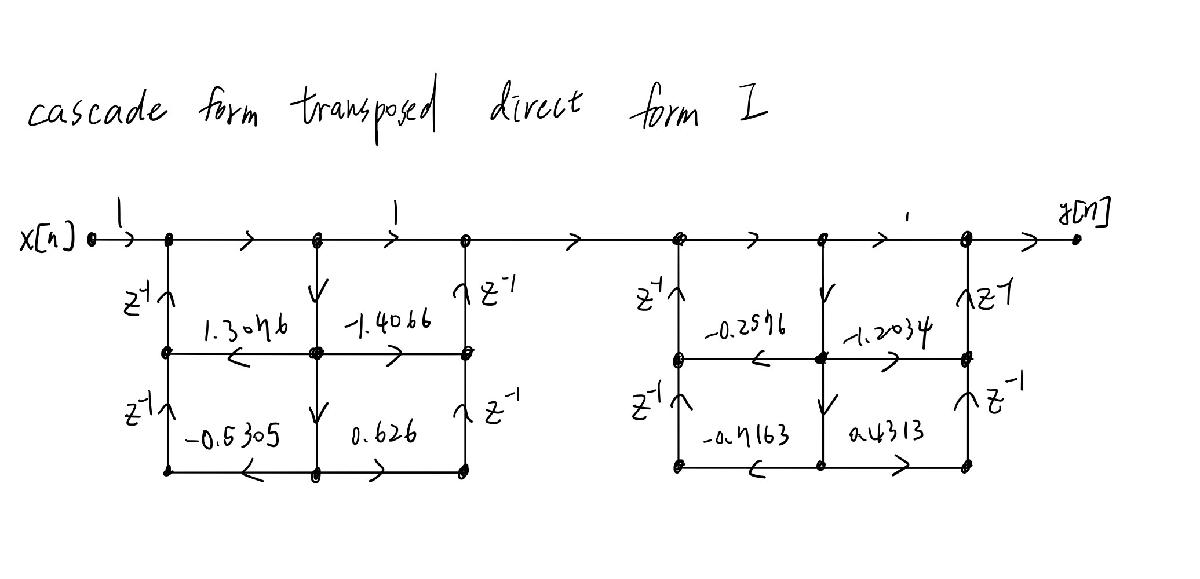

(c)

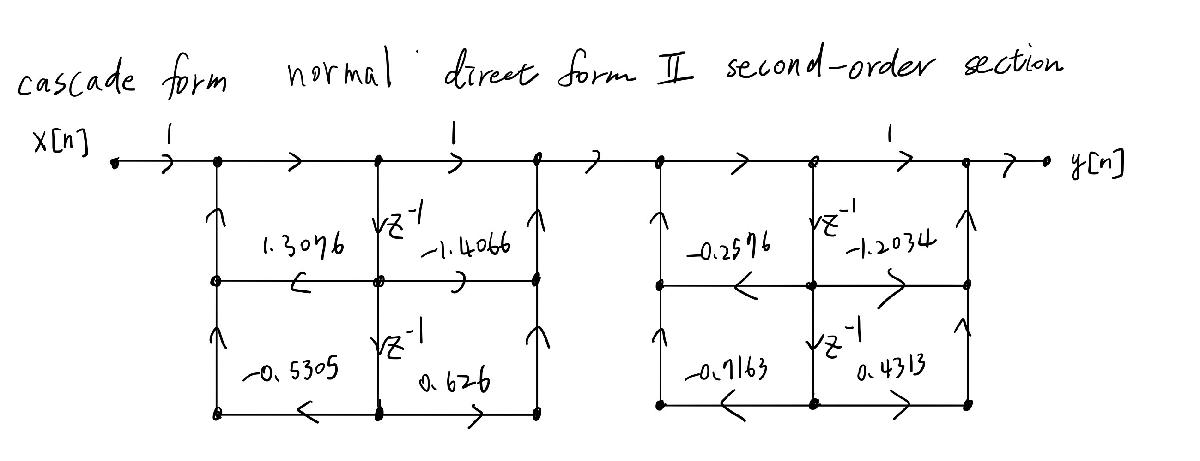

(d)

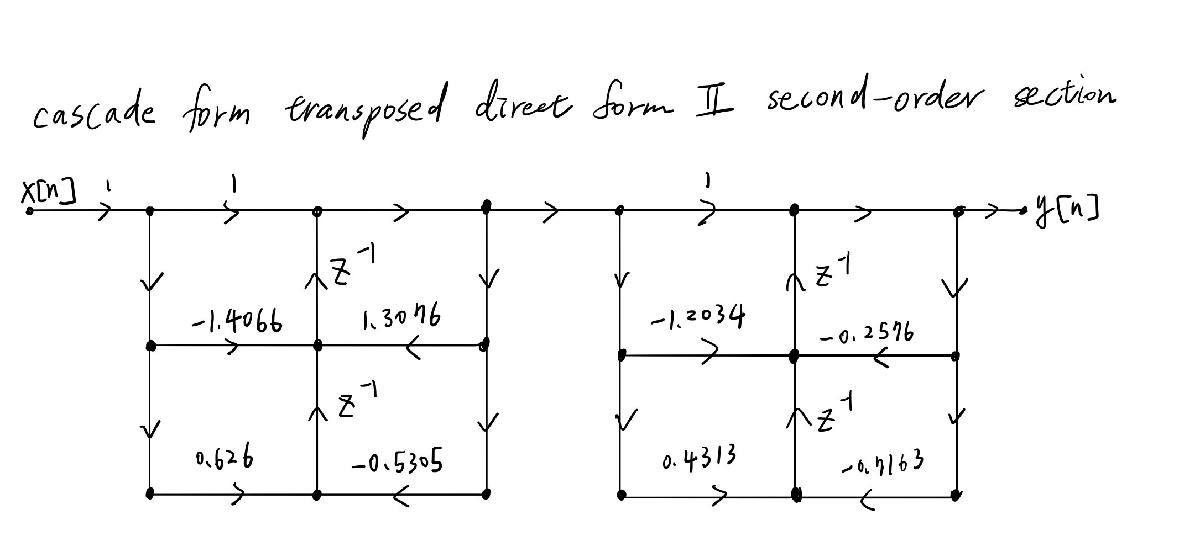

8.

(a)

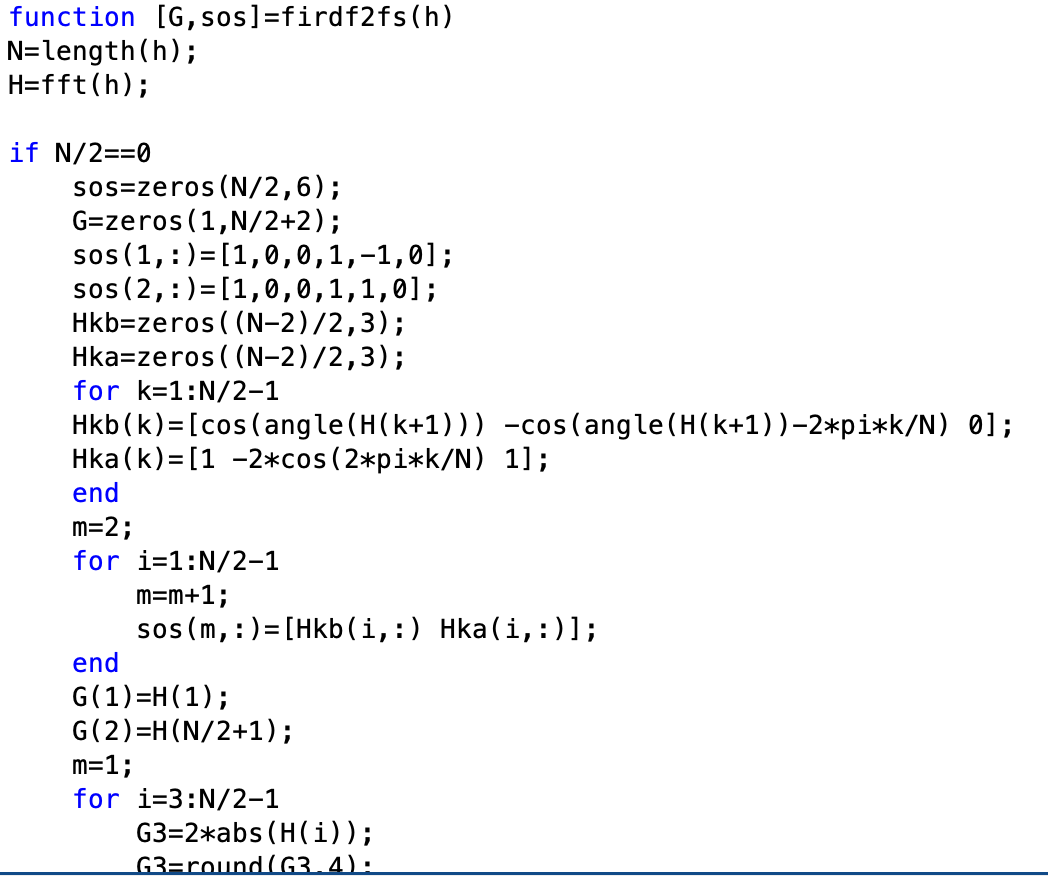

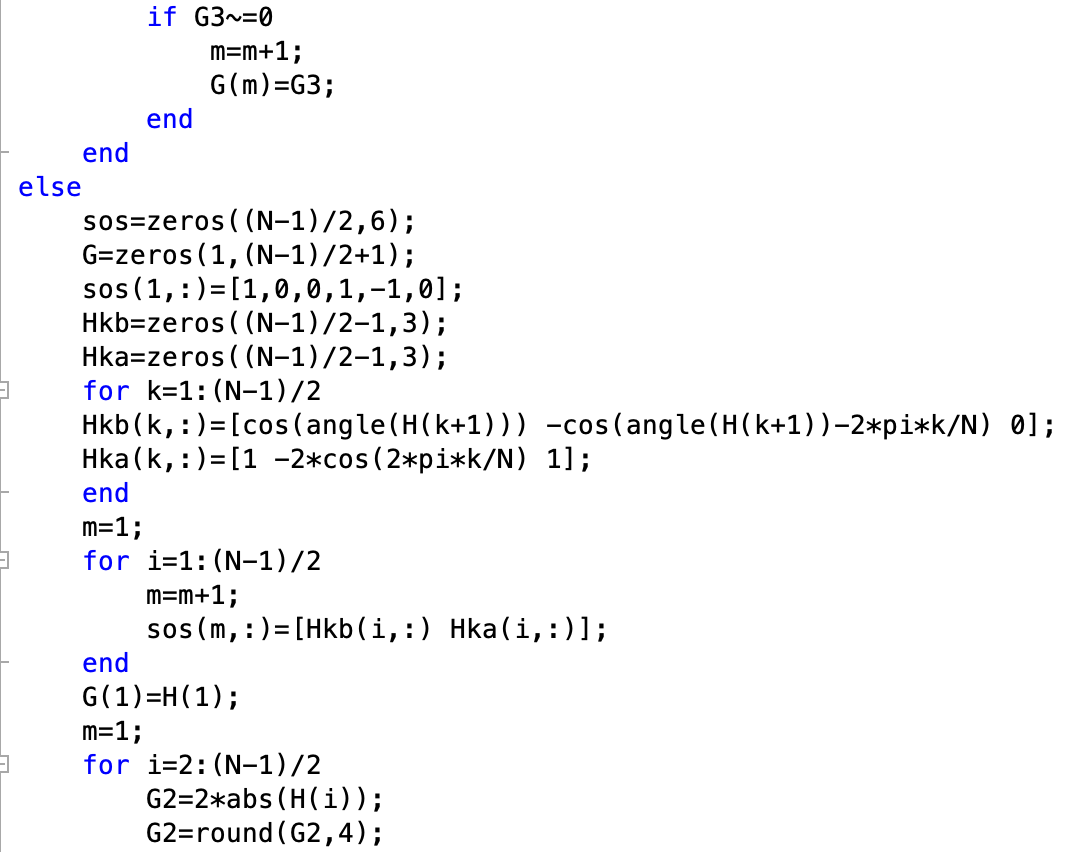

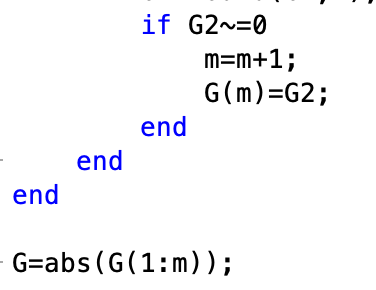

(b)

H=[1 exp(-1j*32*pi/33) exp(-1j*32*pi/33*2) 0.5*exp(-1j*32*pi/33*3) zeros(1,26) 0.5*exp(-1j*32*pi/33*30) exp(-1j*32*pi/33*31) exp(-1j*32*pi/33*32) ];
h=ifft(H);
[G,sos]=firdf2fs(h)

G =      1     2     2     1


sos =     1.0000         0         0    1.0000   -1.0000         0
   -0.9955    0.9955         0    1.0000   -1.9639    1.0000
    0.9819   -0.9819         0    1.0000   -1.8567    1.0000
   -0.9595    0.9595         0    1.0000   -1.6825    1.0000
    0.9516   -0.4766         0    1.0000   -1.4475    1.0000
    0.0787   -0.8577         0    1.0000   -1.1601    1.0000
    0.1670    0.8275         0    1.0000   -0.8308    1.0000
   -0.9985    0.2881         0    1.0000   -0.4715    1.0000
   -0.8240    0.6051         0    1.0000   -0.0952    1.0000
    0.0000   -0.9898         0    1.0000    0.2846    1.0000


9.54括弧裡的那4項即為H[0]、H[N/2]、和2|H[k]|等係數產生的，因N＝33為奇數，所以沒有H[N/2]那項

2|H[k]|的範圍是k從1到16，而只有k=1,2,3時 |H[k]|有值，所以9.54括弧裡總共只有4項

G的4項值為1/2/2/1，與H[0]/2|H[1]|/2|H[2]|/2|H[3]|相同，其他H[k]值為0，所以G只有4項，驗證G正確

sos代表的是9.54括弧裡還未乘上G的分子與分母係數，對應前4項sos的右邊3隔，分別是1,-1/1,-1.9639,1/1,-1.8567,1/1,-1.6825,1

皆與9.54括弧裡那4項的分母係數十分接近，分子的部份乘相對的G後:

先將G後面補0

G=[G zeros(1,length(sos)-length(G))];
for i=1:length(sos)
    sos(i,1:3).*G(i)
end

ans =      1     0     0


ans =    -1.9909    1.9909         0


ans =     1.9639   -1.9639         0


ans =    -0.9595    0.9595         0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


ans =      0     0     0


與9.54括弧裡的分子係數都相同

表示sos正確